# Case study 3: Circuits as Resonators, Sensors, and Filters

**ESE 105** 

**Name: FILL IN HERE**

clear;
close all;

Fs = 192000;   % Sampling frequency, Hz

## Task 1: Tuning fork

Vpulse = zeros(length(0:(1/Fs):5),1);     % 5-second duration
Vpulse(2) = 1;

Vringing = myResonatorCircuit(Vpulse,1/Fs);
soundsc(Vringing,Fs);
pause(5);

## Task 2: Audio sensor

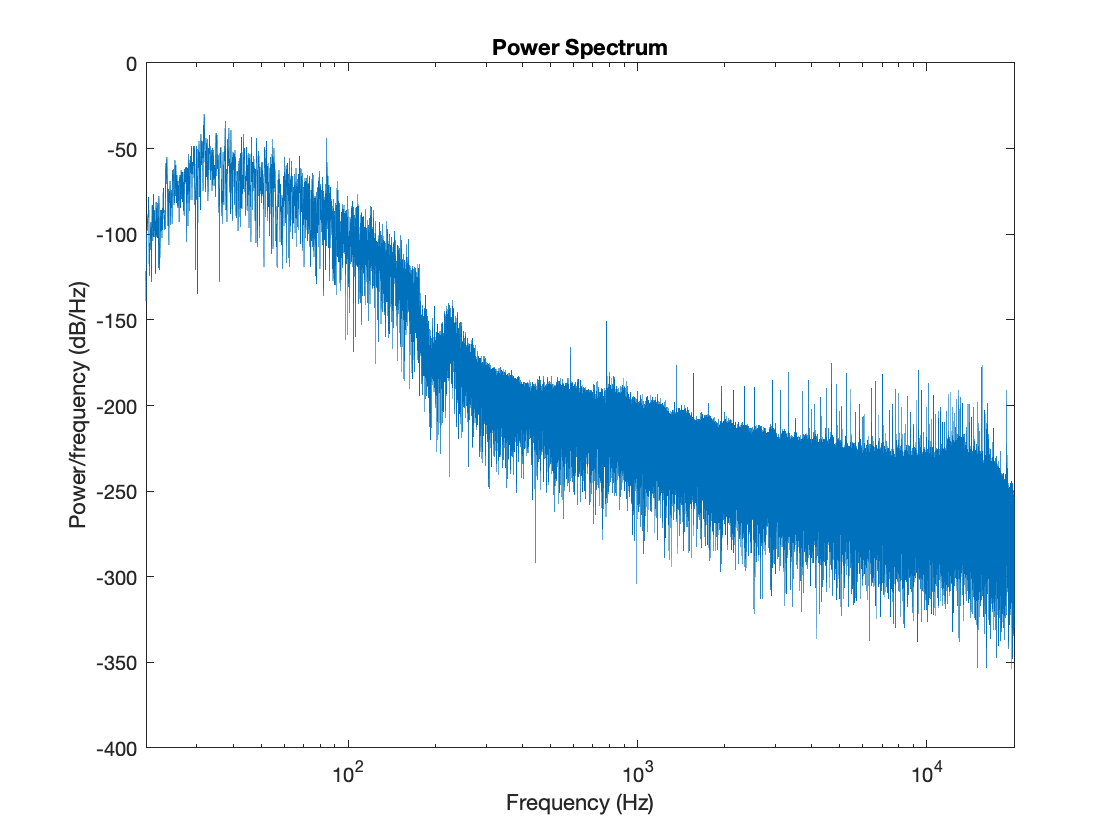

load('MarsHelicopter_noisy.mat');
% set sampling interval to match sampling rate of the audio signal
h = 1/Fs;

% compute signal output from circuit
VsoundFiltered = mySensorCircuit(Vsound,h);

% compare power spectra
plotPowerSpectrum(Vsound,Fs);

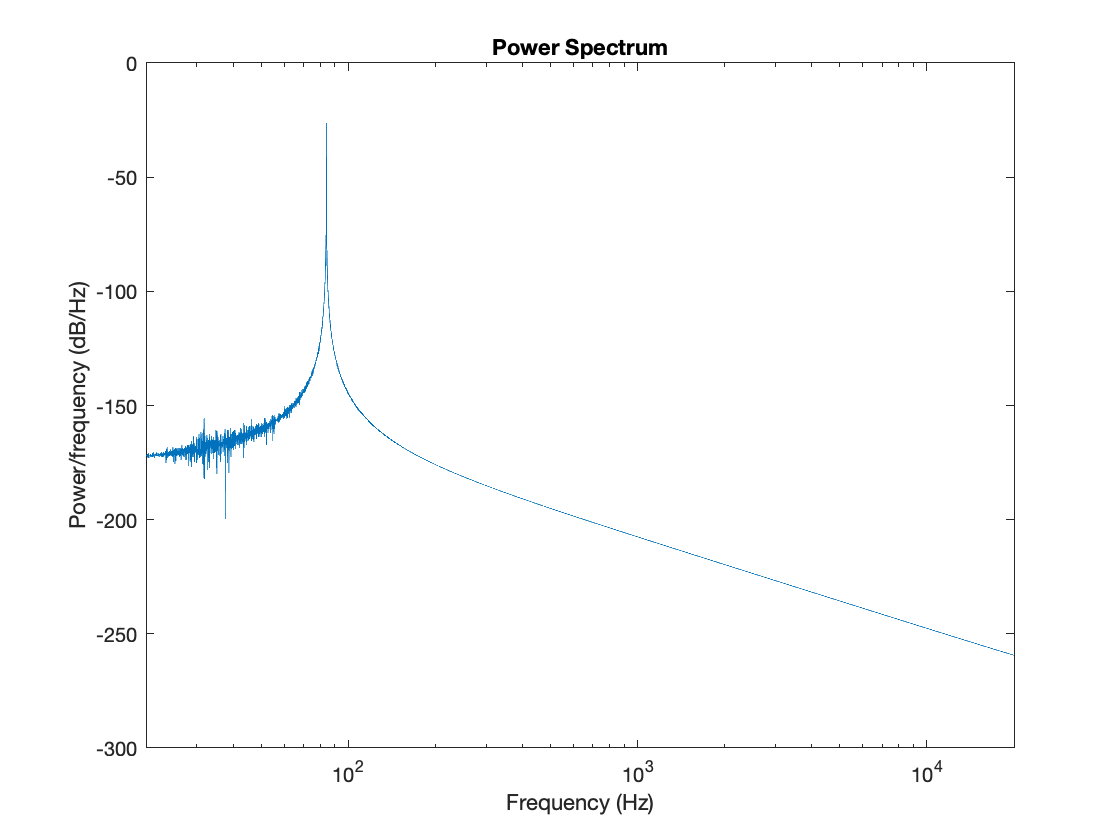

plotPowerSpectrum(VsoundFiltered,Fs);


% play original sound
playSound(Vsound,Fs);

% play sound after circuit filter
playSound(VsoundFiltered,Fs);

## Task 3: Music filter

% load('handel.mat');
load('noisyhandel.mat');

% set sampling interval to match sampling rate of the audio signal
h = 1/Fs;

% compute signal output from circuit
VsoundFiltered = myFilterCircuit(Vsound,h);

% compare power spectra
plotPowerSpectrum(Vsound,Fs);
plotPowerSpectrum(VsoundFiltered,Fs);

% play original sound
playSound(Vsound,Fs);

% play sound after circuit filter
playSound(VsoundFiltered,Fs);